clear all
syms s t tau r l c

r = 3;
l = 1;
c = 1/2;

A = [0 -1/c;
    1/l -r/l];
B = [1/c; 0];
C = [0 r];
D = 0;

[n, d] = ss2tf(A,B,C,D)

n =      0     0     6


d =      1     3     2


phi = inv(s*eye(2)-A);
phi_t = ilaplace(phi,s,t);
phi_tau = subs(phi_t,t,t-tau);
x0 = [0;0];
x = phi_t*x0 + int(phi_tau*B,tau,[0 t]);
y = C*x

$$y = 3\,{\mathrm{e}}^{-2\,t}\,{\left({\mathrm{e}}^{t}-1\right)}^{2}$$

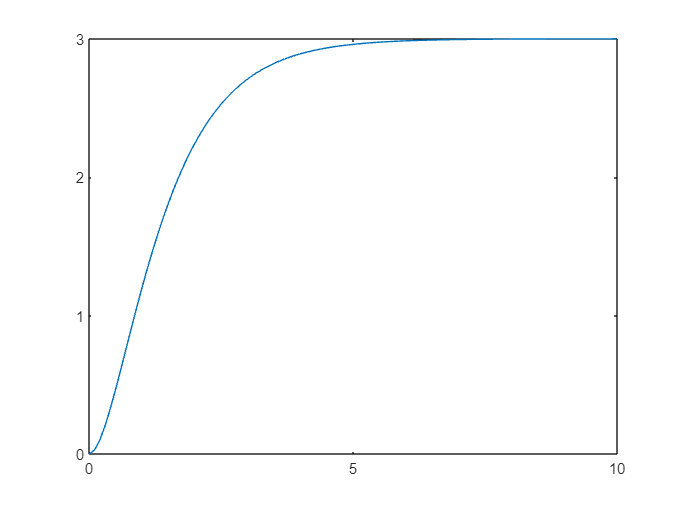

t_ = 0:0.1:10;
plot(t_,subs(y,t,t_))

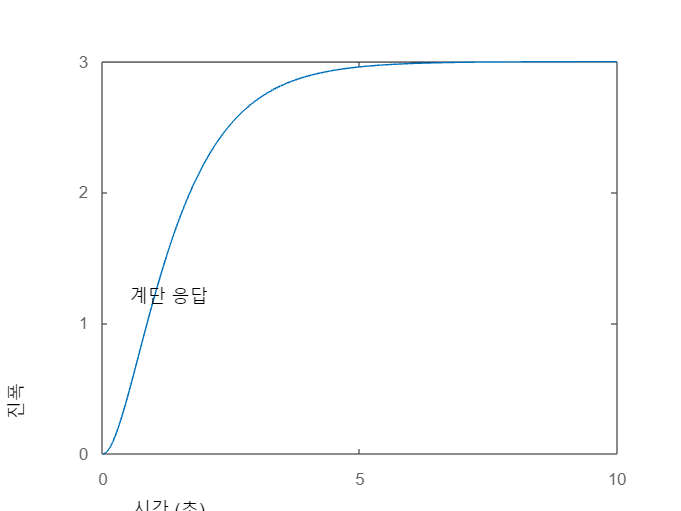


sys = ss(A,B,C,D);
step(sys,10)